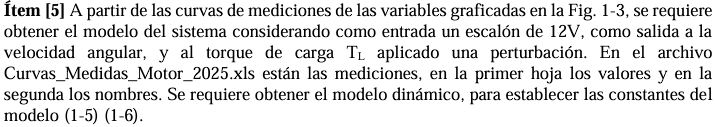

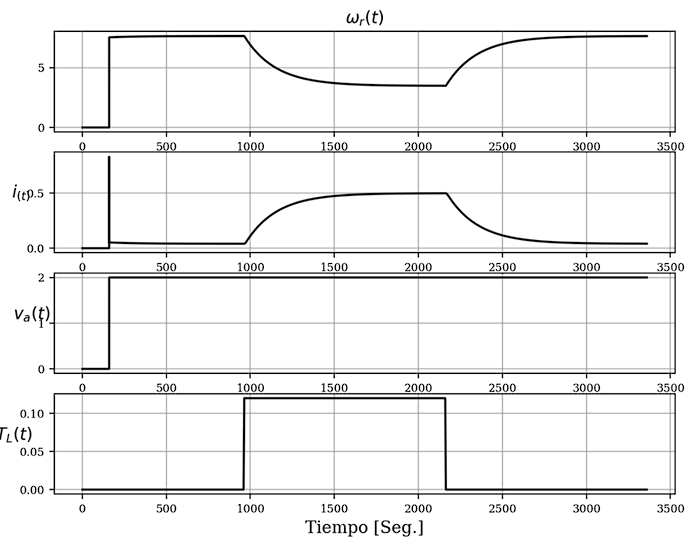

Lectura de datos :  

clear all; clc; close all;

opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "Hoja1";
opts.DataRange = "A2:E1500";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Import the data
tbl = readtable("C:\Users\Maca\Documents\UNC\4toAÑO\1CUATRI\SC2\Folder Github TP´s\Control-System-II-TP-s\TP1\documentation\Curvas_Medidas_Motor_2025_v.xls", opts, "UseExcel", false);

t = tbl.VarName1;
Wr = tbl.VarName2;
Ia= tbl.VarName3;
Va= tbl.VarName4;
Tq = tbl.VarName5;
clear opts tbl

Gráficas: 

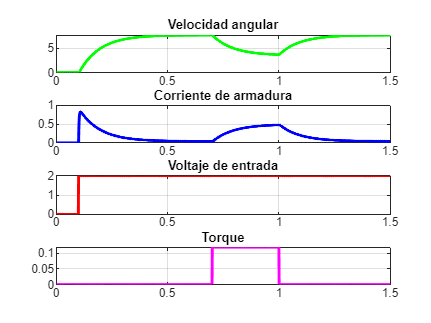

figure; % Creación de la figura sin especificar un número, MATLAB asignará automáticamente
hold on

subplot(4,1,1);
plot(t, Wr, 'g', 'LineWidth', 2);
title('Velocidad angular');
grid on;

subplot(4,1,2);
plot(t, Ia, 'b', 'LineWidth', 2);
title('Corriente de armadura');
grid on;

subplot(4,1,3);
plot(t, Va, 'r', 'LineWidth', 2);
title('Voltaje de entrada'); 
grid on;

subplot(4,1,4);
plot(t,Tq, 'm', 'LineWidth', 2);
title('Torque'); 
grid on;
hold off

Aplico Chen para encontrar Wr/Va

% Apply The Second-Order Systems with differents poles method 

% y(t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(t1/T1))- (((T3-T2)/(T1-T2))*exp(-t1/T2)));
% y(2*t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(2*t1/T1))- (((T3-T2)/(T1-T2))*exp(-(2*t1)/T2)));
% y(3*t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(3*t1/T1))- (((T3-T2)/(T1-T2))*exp(-(3*t1)/T2)));

% Obtain maximium value from t (RLC circuit measure).
max_t= max(t);

% Define step amplitude.
A= 2;

% Take time and voltage arrays
% Time array.
t0= t;
%Vc array.
y=Wr;

%Implementación de Método de CHen para G(s)=Wr/Va
% Take three point to apply Chen Method.

%i=155;
i=160;
t_inic= t0(i);
% Define step.
%h= 62;
h=61;
% Obtain y1.
t_t1= t0(i);
y_t1= y(i)/A

y_t1 = 1.7677

% Obtain y2.
t_2t1= t0(i+h)

t_2t1 = 0.2220

y_2t1= y(i+h)/A

y_2t1 = 2.7583

% Obtain y3.
t_3t1= t0(i+(2*h))

t_3t1 = 0.2830

y_3t1= y(i+(2*h))/A

y_3t1 = 3.2703


% Normalize gain
% Add abs(y(end)), because 'end' take value= -12V (Alternate input signal).
K= abs(y(end))/(A)

K = 3.8093


% Calculating k1, k2, k3.
k1= ((y_t1)/K)-1;
k2= ((y_2t1)/K)-1;
k3= ((y_3t1)/K)-1;

% Calculating b, alfa1, alfa2.
b= 4*(k1^(3))*k3- 3*(k1^2)*(k2^2)- 4*(k2^3)+ (k3^2)+ 6*k1*k2*k3;
alfa1= (k1*k2+ k3- sqrt(b))/(2*((k1^2)+ k2));
alfa2= (k1*k2+ k3+ sqrt(b))/(2*((k1^2)+ k2));

% Calculating Beta.
% beta= (2*(k1^3)+ 3*k1*k2+ k3- sqrt(b))/(sqrt(b));
% Alternative
beta= (k1+alfa2)/(alfa1-alfa2);


% Calculo las ctes de tiempo T1, T2 y T3.
% A t_t1 le resto 0.1 seg. del retardo
desp=0.1

desp = 0.1000

T1= -(t_t1-desp)/(log(alfa1))

T1 = 0.0206

T2= -(t_t1-desp)/(log(alfa2))

T2 = 0.0913

T3= beta *(T1- T2)+ T1

T3 = 0.0170


% Build Transfer Function
s= tf('s');
sys= (K*(T3*s+1))/((T1*s+1)*(T2*s+1)); %%sin retardo
sys1= exp(-s*desp)*sys


sys1 =
 
                     0.06463 s + 3.809
  exp(-0.1*s) * ---------------------------
                0.001876 s^2 + 0.1118 s + 1
 
Continuous-time transfer function.
Model Properties


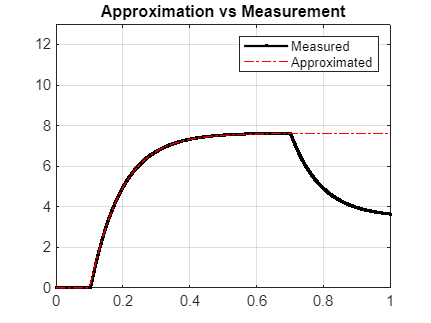

% [num, den]= tfdata(sys, 'v');

% Plot approximated step response
% Obtain step response with delay.
% [ys, ts]= step(sys*exp(-s*0.01), 'r-', 0.16);
figure;
[ys, ts]= step(A*sys1, 'r-', 1.5);   %aproximada
plot(t, Wr, 'k.-','LineWidth',1.5); %medida 
hold on;
plot(ts, ys, 'r-.');%aproximada
xlim([0, 1]);
ylim([0, 13]);
legend('Measured', 'Approximated');
title('Approximation vs Measurement');
grid on;

Aplico Chen para encontrar Wr/TL